# Výpočet zážehového motoru

clc;
clear all;
close all;

### Vstupní data

a=not(true); % input('Zadejte  1 pro standardní vstupy, 0 pro zadání hodnot:');
if a
%-------------------------Standardní vstupní data---------------------
%----------Parametry motoru------
V=2.5;                    % [l] Engine Displacement Volume(Litr)
N=4;                      % [-] Number of Cylinders
n=3000;                   % [1/min] Engine Speed(rpm)
r_c=8.6;                  % [-] Compression Ratio
X=1.025;                  % [-] Stroke-to-Bore Ratio S/B
eta_m=0.86;               % [-] Mechanical Efficiency
EGR=4;                    % [-] Internal EGR Percentage

%---------Fuel Inputs/Combustion Efficiency----
x=8;                      % [-] number of Carbon atoms
y=18;                     % [-] number of Hydrogen atoms
AF=15;                    % [-] Air-Fuel Ratio
eta_conv=1;               % [-] Combustion Efficiency

%Properties of Working Fluids---------------- 
%a constant average value between two exteremes ( SOC & EOCombustion)
K=1.35;                   % [-] Specific Heat Ratio of Air
R=0.287;                  % [kJ/kg.K] Particular Gas Constant of Air                ()
C_v=0.821;                % [kJ/kg.K] Specific Heat for Constant Volume of Air      (kJ/kg)
C_p=R+C_v;                % [kJ/kg.K] Specific Heat for Constant Pressure of Air    (kJ/kg)

%---------Atmospheric Inputs------------
P_0=100;                  % [kPa] Barometrický tlak
T_0=60;                   % [°C] Combustion Chamber Temperature at Start of Compression
row_0=P_0/(R*(293.15));   % [kg/m^3 Hustota vzduchu v referenčních podmínkách 
%-----------------------------------------------------------------
else
%-----------------------Arbitrary Input Data------------------
%----------Engine Inputs------
V=input('Zdvihový objem motoru [litr] : ');
N=input('Počet válců motoru : ');
n=input('Import Engine Speed(rpm): ');
r_c=input('Import Compression Ratio: ');
X=input('Import Stroke-to-Bore Ratio S/B: ');
eta_m=input('Import Mechanical Efficiency:');
EGR=input('Import Internal EGR Percentage: % ');
%---------Fuel Inputs/Efficiencies----
disp('---------------CxHy Složení paliva------------ ');
x=input('Počet atomů uhlíku v palivu: ');
y=input('Please import number of Hydrogen atoms: ');
b=x/y;
AF_s=(34.56*(b+4))/(12.011+(1.008*b));     % Stoichiometrický poměr Vzduch/Palivo (Heywood (5-3))
Z= ['For Complete Combustion Assumption The Air-Fuel Ratio Must be ',num2str(AF_s),' or Higher'];
disp(Z)
AF=input('Import Air-Fuel Ratio: ');
eta_conv=input('Import Combustion Efficiency: ');
%---------Atmosferické podmínky------------
P_0=input('Import Atmospheric Pressure (kPa): ');
T_0=input('Import Combustion Chamber Temperature at Start of Compression(Deg C) : ');
R=input('Import Particular Gas Constant of Air  (kJ/kg.K) : ');
K=input('Import Specific Heat Ratio of Air : ');
C_v=input('Import Specific Heat for Constant Volume of Air (kJ/kg) : ');
C_p=R+C_v;                %Specific Heat for Constant Pressure of Air    (kJ/kg)
row_0=P_0/(R*(293.15));   %Density of Air at Reference Condition         (kg/cubic meter) 
end

### Výpočet

%--------Palivo přívod tepla & účinnost spalování----
M_C=(x*12)/((x*12)+(y));                           % Hmotnostní podíl uhlíku v palivu
M_H=(y*0.68)/((x*12)+(y));                         % Hmotnostní podíl vodíku v palivu
FHV=((14600*M_C)+(62000*M_H))*2.326;               % [kJ/kg] Výhřevnost paliva [Dulong s formula]
b=x/y;
AF_s=(34.56*(b+4))/(12.011+(1.008*b));             % Stechiometrický poměr Vzduch/Palivo (Heywood (5-3))
lambda=AF/AF_s;
Th_Air=lambda*100;                                 % Teoretický podíl vyduchu
EAP=Th_Air-100;                                    % Exess Air Percentage

if lambda >= 1                                    
    eta_ch=1;
else
    eta_ch=(1.3773*lambda)-0.3773;                 %Schmidt (1996)
end
eta_c=eta_conv*eta_ch;                             %Pischinger (1989)

#### Pro jeden válec

V_d=(V/N)/1000;                 % [m^3] Zdvihový objem
V_c=V_d/(r_c-1);                % [m^3] Kompresní objem
B=((4*V_d/pi*X)^(1/3))*100;     % [cm] Vrtání
S=B*X;                          % [cm] Zdvit
A_p=(pi*(B^2))/4 ;              % [cm^2] Plocha pístu

Stav 1 (Začátek komprese) 

T_1=(T_0)+273;                  %Temprature of Gas Mixture in Cylinder at State 1 (Deg K)
P_1=P_0;                        %Pressure of Gas Mixture in Cylinder at State 1   (kPa)
V_1=V_d+V_c;                    %Volume of Gas Mixture in Cylinder at State 1     (Cubic Meter)

%----Mass of Gases Calculation------
M_m=(P_1*V_1)/(R*T_1);   %Mass of Gas Mixture in Cylinder (kg)

%the mass within the cylinder will then remain the same for the entire
%cycle

M_a=(AF/(AF+1))*((100-EGR)/100)*M_m;    %Mass of Air in Cylinder                         (kg)
M_f=(1/(AF+1))*((100-EGR)/100)*M_m;     %Mass of Fuel in Cylinder                        (kg)
M_ex=(EGR/100)*M_m;                     %Mass of Exhaust Residual in Cylinder at SOC     (kg)
   

Stav 2 (Začátek spalování)

T_2=(T_1)*((r_c)^(K-1));                %Temprature of Gas Mixture in Cylinder at State 2 (K)
P_2=(P_1)*((r_c)^K);                    %Pressure of Gas Mixture in Cylinder at State 2   (kPa)
V_2=V_1/r_c;                            %Volume of Gas Mixture in Cylinder at State 2     (Cubic Meter)

State 3 (Konec spalování)

T_3=((FHV*eta_c)/((AF+1)*C_v))+T_2;     %Temprature of Gas Mixture in Cylinder at State 3 (Deg K)
P_3=(P_2/T_2)*T_3;                      %Pressure of Gas Mixture in Cylinder at State 3   (kPa)
V_3=V_2;                                %Volume of Gas Mixture in Cylinder at State 3     (Cubic Meter)

%----Pressure Ratio (Change in Pressure During Combustion)--

Alpha=P_3/P_2;                          %Pressure Increase During Contant-Volume Combustion 


%------------State 4 (End of Expression)-----

T_4=T_3*((1/r_c)^(K-1));                %Temprature of Gas Mixture in Cylinder at State 4 (Deg K)
P_4=P_3*((1/r_c)^K);                    %Pressure of Gas Mixture in Cylinder at State 4   (kPa)
V_4=(M_m*R*T_4)/P_4;                    %Volume of Gas Mixture in Cylinder at State 4     (Cubic Meter)


%------------State 5 

T_5=T_1;                                %Temprature of Gas Mixture in Cylinder at State 5 (Deg K)
P_5=P_1;                                %Pressure of Gas Mixture in Cylinder at State 5   (kPa)
V_5=V_1;                                %Volume of Gas Mixture in Cylinder at State 5     (Cubic Meter)

%------------State 6 

T_6=T_0;                                %Temprature of Gas Mixture in Cylinder at State 6 (Deg K)
P_6=P_0;                                %Pressure of Gas Mixture in Cylinder at State 6   (kPa)
V_6=V_2;                                %Volume of Gas Mixture in Cylinder at State 6     (Cubic Meter)

#### Děje

Děj 1-2 (Kompresa)

Q_12=0;
W_12=M_m*C_v*(T_1-T_2);     % [kJ]

2-3 Process (Combustion)

Q_23=M_f*FHV*eta_c;         % [kJ]
W_23=0;

3-4 Process (Expression)

Q_34=0;
W_34=M_m*C_v*(T_3-T_4);     %  [kJ]

4-5 Process  (Exhaust)

Q_45=M_m*C_v*(T_5-T_4);     % [kJ] 
W_45=0;

### Overal Engine Performance

U_p=2*S*n*(1/6000);                         % (m/s) Střední pístová rychlost
W_i=W_12+W_34;                              %Net Indicated Work for One Cylinder During One Cycle (kJ)
Q_in=M_f*FHV*eta_c;                         %Heat Added for One Cylinder During One Cycle         (kJ)
eta_t=W_i/Q_in;                             %Thermal Efficiency
imep=W_i/(V_d);                             %Indicated Mean Effective Pressure                    (kPa)
bmep=imep*eta_m;                            %Brake Mean Effective Pressure                        (kPa)
W_idat=W_i*N*(n/(60*2));                    %Indicated Power at {n} RPM                           (KW)
W_b=eta_m*W_i;                              % [kJ] Net Brake Work for One Cylinder During One Cycle     (kJ)
W_bdat=W_b*N*(n/(60*2));                    % [kW] Brake Power at {n} RPM                               (KW)
Taw=(W_bdat/(2*pi*(n/60)))*1000;            % [N.m] Torque                                               
W_fdat=W_idat-W_bdat;                       % [kW] Friction Power Lost                                  
BSP=W_bdat/A_p;                             % [kW] Brake Specific Power                                 (KW/square cm)
OPD=W_bdat/V;                               % [kW] Outpot per Displacement                              (KW/Litr)
M_fdat=M_f*(n/60)*(1/2)*N;                  %Rate of Fuel That Inject in All Cylinder During One Cycle (kg/sec)
bsfc=(M_fdat/W_bdat)*3600000;               %Brake Specific Fuel Consumption                      (gr/KW-hr)
eta_v=M_a/(row_0*V_d);                      % Objemová účinnost

### Zobrazení výsledků

disp('---------------------Palivo & Vlastnosti spalování------------------------ ');

---------------------------Fuel & Combustion Properties-------------------------- 


F=[x y];
disp('     C     H')

     C     H


disp(F)

     8    18



A = ['The Actual Air/Fuel Ratio is: ',num2str(AF)];
disp(A)  

The Actual Air/Fuel Ratio is: 15


Z = ['The Stoichiometric Air/Fuel Ratio is: ',num2str(AF_s)];
disp(Z)

The Stoichiometric Air/Fuel Ratio is: 12.3284


T=['The Percent of Theoritical Air is: ',num2str(Th_Air)];
disp(T)

The Percent of Theoritical Air is: 121.6699


E=['The Percent of Excess Air is: ',num2str(EAP)];
disp(E)

The Percent of Excess Air is: 21.6699


Eff=['Total Combustion Efficiency is: ',num2str(eta_c)];
disp(Eff)

Total Combustion Efficiency is: 1


HV=['Fuel Heating Value is: ',num2str(FHV), ' kJ/kg'];
disp(HV)

Fuel Heating Value is: 44081.3726 kJ/kg


disp('                                                                   ');

disp('-------------------Cycle Operating Point Properties-------------------------- ');

---------------------------Cycle Operating Point Properties-------------------------- 


disp('                                                                   ');

aa=['Maximálni teplova v cyklu : ',num2str(T_3-273.15), ' °C'];
disp(aa)

The Maximum Temprature of The Cycle is: 3789.78 Deg C


ab=['Maximální tlak v cyklu is : ',num2str(P_3), ' kPa'];
disp(ab)

The Maximum Pressure of The Cycle is : 10492.8521 kPa


disp('                                                                   ');

disp('---------------------------Celkové výkonnové parametry motoru --------------- ');

---------------------------Overal Engine Performances-------------------------- 


disp('                                                                   ');

a15=['The Mean Piston Speed is: ',num2str(U_p),' m/s'];
disp(a15)

The Mean Piston Speed is: 9.577 m/s


a1=['The Thermal Efficiency is: ',num2str(eta_t)];
disp(a1)

The Thermal Efficiency is: 0.55115


a2=['The Indicated Mean Effective Pressure imep is : ',num2str(imep), ' kPa'];
disp(a2)

The Indicated Mean Effective Pressure imep is : 1725.9747 kPa


a3 = ['The Brake Mean Effective Pressure is : ',num2str(bmep), ' kPa'];
disp(a3)  

The Brake Mean Effective Pressure is : 1484.3382 kPa


a5 = ['The Indicated Power at ',num2str(n),' RPM is : ',num2str(W_idat), ' KW'];
disp(a5)

The Indicated Power at 3000 RPM is : 107.8734 KW


a6 = ['The Brake Power at ',num2str(n),' RPM is : ',num2str(W_bdat), ' KW'];
disp(a6)

The Brake Power at 3000 RPM is : 92.7711 KW


a8=['The Friction Power Lost is: ',num2str(W_fdat), ' KW'];
disp(a8)  

The Friction Power Lost is: 15.1023 KW


a7 = ['The Torque at ',num2str(n),' RPM is : ',num2str(Taw), ' N-m'];
disp(a7)    

The Torque at 3000 RPM is : 295.2997 N-m


a9=['The Brake Specific Fuel Consumption bsfc is : ',num2str(bsfc), ' gr/KW-hr'];
disp(a9)

The Brake Specific Fuel Consumption bsfc is : 172.2978 gr/KW-hr


a12 = ['The Volumetric Efficiency is : ',num2str(eta_v)];
disp(a12)

The Volumetric Efficiency is : 0.89655


a10 = ['The Outpot per Displacement OPD is : ',num2str(OPD), ' KW/Litr'];
disp(a10)

The Outpot per Displacement OPD is : 37.1085 KW/Litr


a11 = ['The Brake Specific Power BSP is : ',num2str(BSP), ' KW/cm^2'];
disp(a11)

The Brake Specific Power BSP is : 1.353 KW/cm^2


a13 = ['The Pressure Increase Ratio During Contant-Volume Combustion is : ',num2str(Alpha)];
disp(a13)

The Pressure Increase Ratio During Contant-Volume Combustion is : 5.7454


### Kreslení grafů

p-V diagram

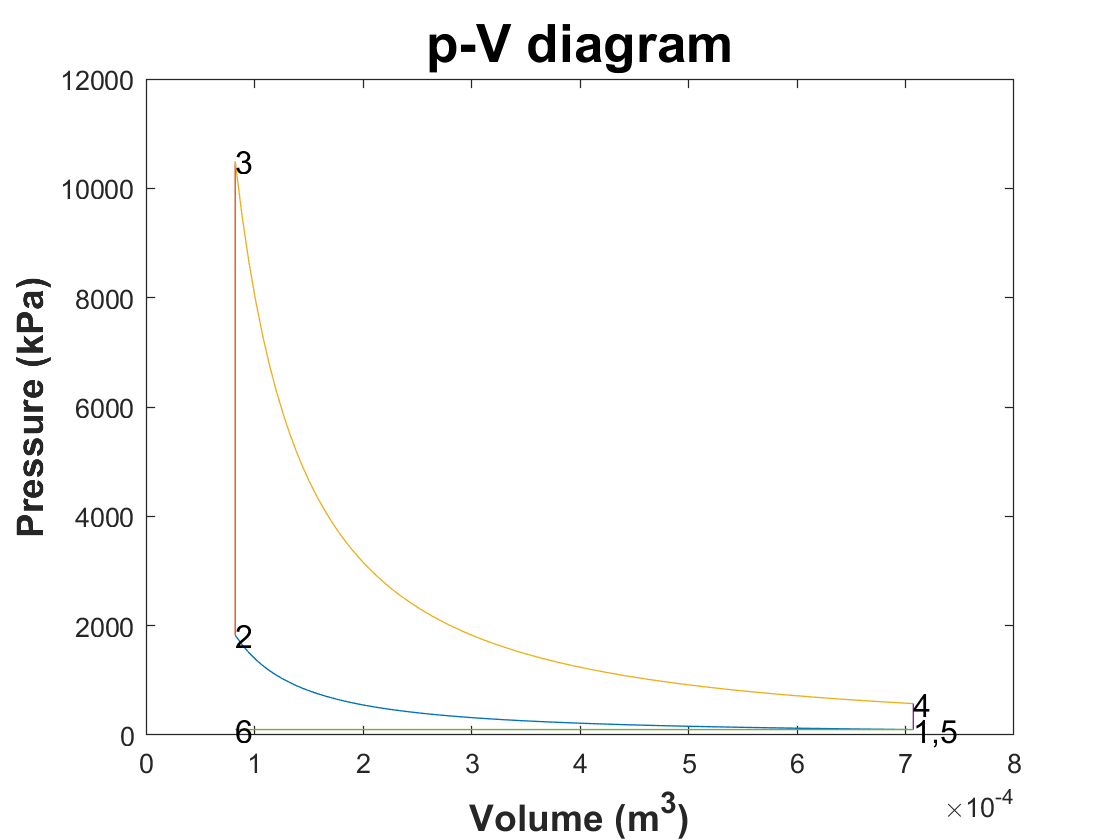

%---Plot 1-2 Process (Compression)
V_12=linspace(V_1,V_2,100);
P_12=((V_1./V_12).^K)*P_1;
plot(V_12,P_12);
title('p-V diagram','FontSize', 20 , 'FontName', 'Helvetica','FontWeight','bold');xlabel('Volume (m^3)','FontSize', 14 , 'FontName', 'Helvetica','FontWeight','bold');ylabel('Pressure (kPa)','FontSize', 14 , 'FontName', 'Helvetica','FontWeight','bold');
hold on
%---Plot 2-3 Process (Combustion)
V_23=[V_2 V_3];
P_23=[P_2 P_3];
plot(V_23,P_23);
%---Plot 3-4 Process (Expression)
V_34=linspace(V_3,V_4,100);
P_34=((V_3./V_34).^K)*P_3;
plot(V_34,P_34);
%---Plot 4-1 Process  (Exhaust)
V_41=[V_4 V_1];
P_41=[P_4 P_1];
plot(V_41,P_41);
%---Plot 5-6 Process (Pumping-Expulsion)
V_56=[V_5 V_6];
P_56=[P_5 P_6];
plot(V_56,P_56);

hold off

text(V_1,P_1, '1,5' ,  'FontSize' ,12)
text(V_2,P_2, '2' ,  'FontSize' ,12)
text(V_3,P_3, '3' ,  'FontSize' ,12)
text(V_4,P_4, '4' ,  'FontSize' ,12)
text(V_6,P_6, '6' ,  'FontSize' ,12)

figure;

T-S Diagram

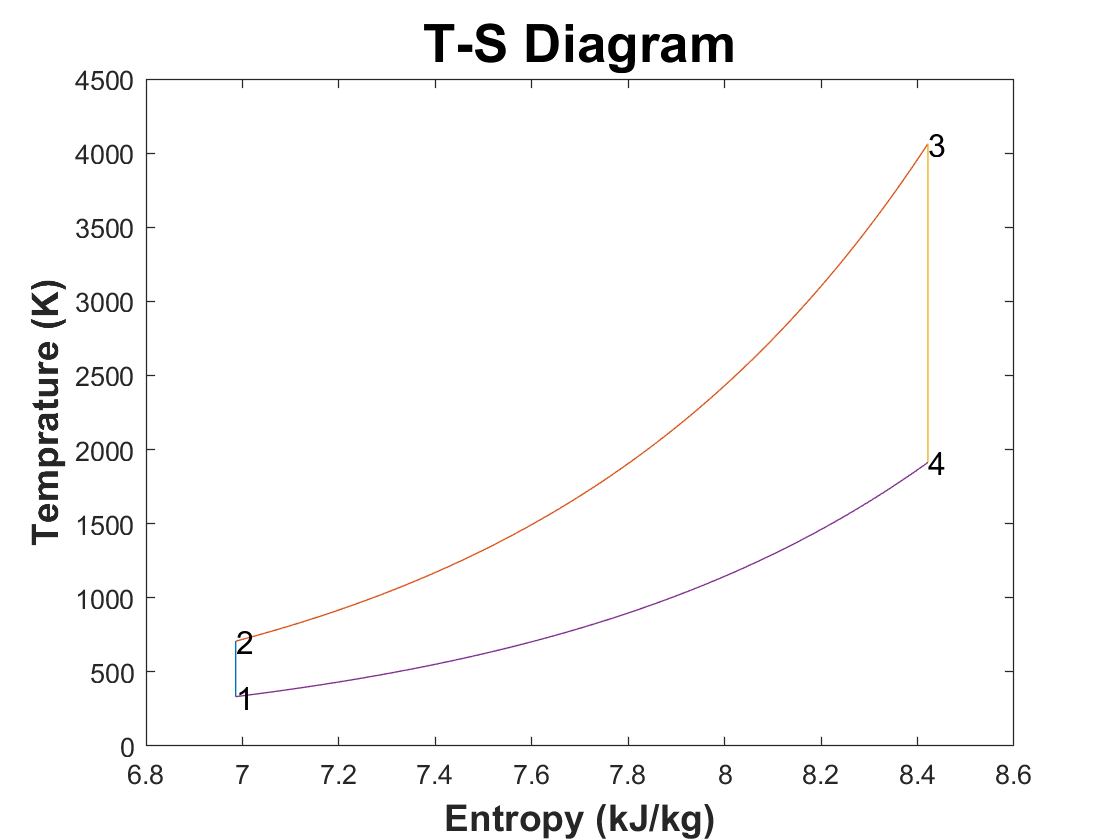

%Refference State:   ( Table A/12SI Van Wylen Ed.4 )
Pref=P_0;            % 0.1 (MPa)
Tref=298.15;         % 25 Deg C
Sref=6.86305;        % (kJ/kgK)
%---Plot 1-2 Process (Compression)
S_1=Sref+(C_p*log((T_0+273.15)/Tref));      %( Eq.10-31 Van Wylen Ed.4 )
S_2=S_1;
S_12=[S_1 S_2];
T_12=[T_1 T_2];
plot(S_12,T_12);
title('T-S Diagram','FontSize', 20 , 'FontName', 'Helvetica','FontWeight','bold');xlabel('Entropy (kJ/kg)','FontSize', 14 , 'FontName', 'Helvetica','FontWeight','bold');ylabel('Temprature (K)','FontSize', 14 , 'FontName', 'Helvetica','FontWeight','bold');
hold on
%---Plot 2-3 Process (Combustion)
T_23=linspace(T_2,T_3,100);
S_23=S_2+(C_v*log(T_23/T_2));           %( Eq.10-33 Van Wylen Ed.4 )
S_3=S_2+(C_v*log(T_3/T_2));
plot(S_23,T_23);
%---Plot 3-4 Process (Expression)
S_4=S_3;
S_34=[S_3 S_4];
T_34=[T_3 T_4];
plot(S_34,T_34);
%---Plot 4-1 Process  (Exhaust)
T_41=linspace(T_4,T_1,100);
S_41=S_4+(C_v*log(T_41/T_4));           %( Eq.10-33 Van Wylen Ed.4 )
plot(S_41,T_41);

hold off

text(S_1,T_1, '1' ,  'FontSize' ,12)
text(S_2,T_2, '2' ,  'FontSize' ,12)
text(S_3,T_3, '3' ,  'FontSize' ,12)
text(S_4,T_4, '4' ,  'FontSize' ,12)